# Lane Detection Optimized with GPU Coder

This example shows how to develop a deep learning lane detection application that runs on NVIDIA® GPUs.

The pretrained lane detection network can detect and output lane marker boundaries from an image and is based on the `AlexNet` network.  The last few layers of the `AlexNet` network are replaced by a smaller fully connected layer and regression output layer. The example generates a CUDA® executable that runs on a CUDA-enabled GPU on the host machine.

## Third-Party Prerequisites

- CUDA enabled NVIDIA GPU.

- NVIDIA CUDA toolkit and driver.

- NVIDIA cuDNN library.

- Environment variables for the compilers and libraries. For information on the supported versions of the compilers and libraries, see [Third-party Products](docid:gpucoder_gs#mw_aa8b0a39-45ea-4295-b244-52d6e6907bff). For setting up the environment variables, see [Environment Variables](docid:gpucoder_gs#mw_453fbbd7-fd08-44a8-9113-a132ed383275).

## Verify GPU Environment

Use the [coder.checkGpuInstall](docid:gpucoder_ref#mw_0957d820-192f-400a-8045-0bb746a75278) function to verify that the compilers and libraries necessary for running this example are set up correctly.

## Get Pretrained Lane Detection Network

This example uses the `trainedLaneNet` MAT-file containing the pretrained lane detection network. This file is approximately 143 MB size. Download the file from the MathWorks® website.

laneNetFile = matlab.internal.examples.downloadSupportFile('gpucoder/cnn_models/lane_detection', ...
    'trainedLaneNet.mat');

This network takes an image as an input and outputs two lane boundaries that correspond to the left and right lanes of the ego vehicle. Each lane boundary is represented by the parabolic equation: $y = ax^2+bx+c$, where y is the lateral offset and x is the longitudinal distance from the vehicle. The network outputs the three parameters a, b, and c per lane. The network architecture is similar to `AlexNet` except that the last few layers are replaced by a smaller fully connected layer and regression output layer.

load(laneNetFile);
disp(laneNet)

  SeriesNetwork with properties:

         Layers: [23×1 nnet.cnn.layer.Layer]
     InputNames: {'data'}
    OutputNames: {'output'}



Convert the `SeriesNetwork` objects to `dlnetwork` objects and save it to a different MAT-file.

dlLaneNet = dag2dlnetwork(laneNet);
dlLaneNetFile = 'trainedDlLaneNet.mat';
save(dlLaneNetFile,'dlLaneNet');

## **Download Test Video**

To test the model, the example uses the a video file from the Caltech lanes dataset. The file is approximately 8 MB in size. Download the file from the MathWorks website.

videoFile = matlab.internal.examples.downloadSupportFile('gpucoder/media','caltech_cordova1.avi');

## Main Entry-Point Function

The `detectLanesInVideo.m` file is the main entry-point function for code generation. The `detectLanesInVideo` function uses the [VideoReader](docid:matlab_ref#busqe2j-1) object to read frames from the input video, calls the predict method of the LaneNet network object, and draws the detected lanes on the input video. A [vision.DeployableVideoPlayer](docid:vision_ref#bse_rxz) system object is used to display the lane detected video output.

type detectLanesInVideo.m

function detectLanesInVideo(videoFile,net,laneCoeffMeans,laneCoeffsStds)
%   Copyright 2022-2024 The MathWorks, Inc.

%#codegen

%% Create Video Reader and Video Player Object 
videoFReader   = VideoReader(videoFile);
depVideoPlayer = vision.DeployableVideoPlayer(Name='Lane Detection on GPU');
videoHeight = videoFReader.Height;
videoWidth = videoFReader.Width;
%% Video Frame Processing Loop
while hasFrame(videoFReader)
    videoFrame = imresize(readFrame(videoFReader),[videoHeight videoWidth]);
    scaledFrame = imresize(videoFrame,[227 227]);

    [laneFound,ltPts,rtPts] = laneNetPredict(net,scaledFrame, ...
        laneCoeffMeans,laneCoeffsStds);
    lnaeFound = 1;
    if(laneFound)
        pts = [reshape(ltPts',1,[]);reshape(rtPts',1,[])];
        videoFrame = insertShape(videoFrame, 'Line', pts, 'LineWidth', 4);
    
    depVideoPlayer(videoFrame);
    end
end



## LaneNet Predict Function

The `laneNetPredict` function computes the right and left lane positions in a single video frame. The `laneNet` network computes parameters a, b, and c that describe the parabolic equation for the left and right lane boundaries. From these parameters, compute the x and y coordinates corresponding to the lane positions. The coordinates must be mapped to image coordinates. 

type laneNetPredict.m

function [laneFound,ltPts,rtPts] = laneNetPredict(net,frame,means,stds) 
%#codegen

% laneNetPredict Predict lane markers on the input image frame using the
% lane detection network

%   Copyright 2017-2024 The MathWorks, Inc.

dlFrame = dlarray(single(frame),'SSC');
persistent dllaneNet;
if isempty(dllaneNet)
    dllaneNet = coder.loadDeepLearningNetwork(net, 'dllaneNet');
end

dllanecoeffsNetworkOutput = predict(dllaneNet,dlFrame);
lanecoeffsNetworkOutput = extractdata(dllanecoeffsNetworkOutput);

% Recover original coeffs by reversing the normalization steps.
params = lanecoeffsNetworkOutput' .* stds + means;

% 'c' should be more than 0.5 for it to be a lane.
isRightLaneFound = abs(params(6)) > 0.5;
isLeftLaneFound =  abs(params(3)) > 0.5;

% From the networks output, compute left and right lane points in the image
% coordinates.
vehicleXPoints = 3:30;
ltPts = coder.nullcopy(zeros(28,2,'single'));
rtPts = coder.nullcopy(zeros(28,2,'single'));

if isRightLaneFound && isLeftLaneFound

## Generate CUDA Executable

To generate a standalone CUDA executable for the `detectLanesInVideo` entry-point function, create a GPU code configuration object for `'exe'` target and set the target language to C++. Use the [coder.DeepLearningConfig](docid:gpucoder_ref#mw_e8e85f8e-8dde-45b6-9ec5-f121a79dc48f) function to create a `CuDNN` deep learning configuration object and assign it to the `DeepLearningConfig` property of the GPU code configuration object. 

cfg = coder.gpuConfig('exe');
cfg.DeepLearningConfig = coder.DeepLearningConfig('cudnn');
cfg.GenerateReport = true;
cfg.GenerateExampleMain = "GenerateCodeAndCompile";
cfg.TargetLang = 'C++';
inputs = {coder.Constant(videoFile),coder.Constant(dlLaneNetFile), ...
    coder.Constant(laneCoeffMeans),coder.Constant(laneCoeffsStds)};

Run the `codegen` command.

codegen -args inputs -config cfg detectLanesInVideo

Code generation successful: View report



## Run the Executable

To run the executable, uncomment the following lines of code.

if ispc
    [status,cmdout] = system("detectLanesInVideo.exe");
else
    [status,cmdout] = system("./detectLanesInVideo");
end

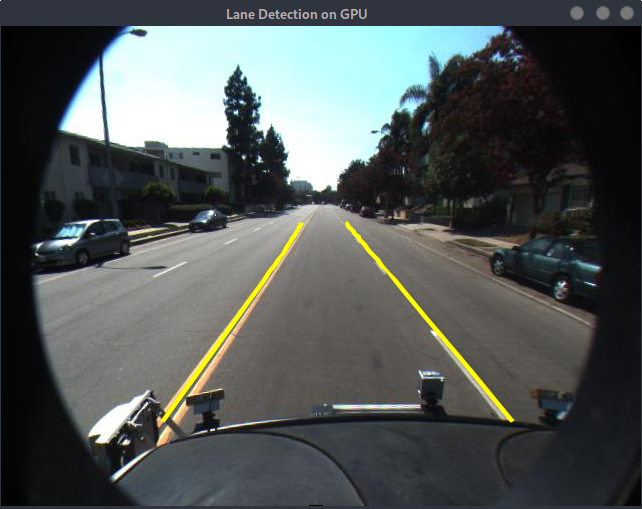

*Copyright 2017-2024 The MathWorks, Inc.*